% img = imread('chessboard.jpg');
% imshow(img);
% img = rgb2gray(img);
% imshow(img)
% 

% % Creating LPF and HPF
% k = 3; % kernel size
% 
% % Initializing kernels for low pass and high pass filters
% lpf = (1/9).*ones(3);
% hpf = (-1/9).*ones(3);
% hpf(2,2) = 8/9;
% 
% % Processing the image using HPF
% img = double(img);
% img_hpf = convImg(img,hpf);
% imshow(uint8(img_hpf));
% 
% % Implementing the harris algorithm
% prewitt_x = [1,0,-1;1,0,-1;1,0,-1];
% prewitt_y = [1,1,1;0,0,0;-1,-1,-1];
% 
% Ix = convImg(img,prewitt_x);
% imshow(uint8(Ix))
% 
% Iy = convImg(img,prewitt_y);
% imshow(uint8(Iy))
% 
% % Defining values for the structure matrix
% Ixx = Ix.*Ix;
% Iyy = Iy.*Iy;
% Ixy = Ix.*Iy;
% 
% % Implementing the Harris Algorithm
% ws = 5; % Window size
% [n,~] = size(Ix);
% k = 0.04;
% T = 1e4;
% corners = zeros(n-ws+1);
% edges = zeros(n-ws+1);
% 
% for i=1:(n-ws+1)
%     for j=1:(n-ws+1)
%         Ixx_m = Ixx(i:i+2,j:j+2);
%         Iyy_m = Iyy(i:i+2,j:j+2);
%         Ixy_m = Ixy(i:i+2,j:j+2);
%         
%         % defining the structure matrix
%         H = 1/(ws^2)*[sum(Ixx_m,"all"), sum(Ixy_m,"all"); sum(Ixy_m,"all"), sum(Iyy_m,"all")];
%         R = det(H) -k*((trace(H))^2);
%         if R>T
%             corners(i,j) = 255;
%         end
%         if R<-T*0.5
%             edges(i,j) = 255;
%         end
%     end
% end
% 
% imshow(uint8(corners))
% imshow(uint8(edges))

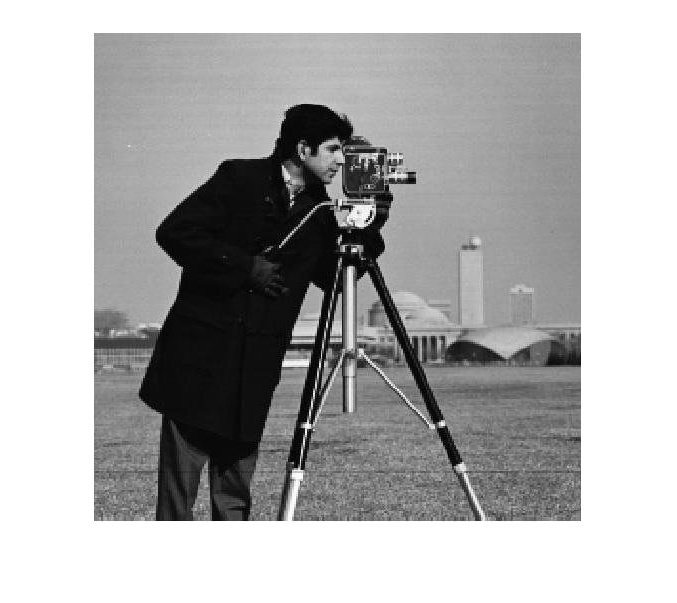

% % Applying Gaussian filter
img2 = imread("cameraman.jpg");
%img2 = rgb2gray(img2);
imshow(img2)

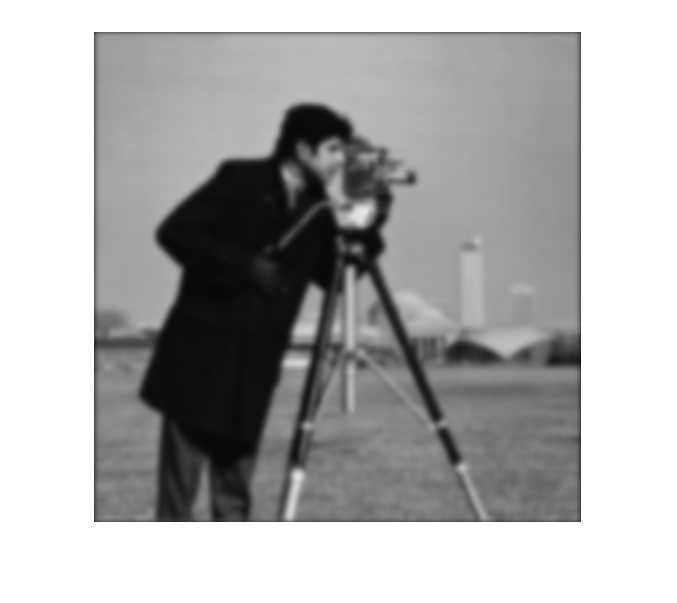

gaussian_img = gaussianFilter(3,double(img2));
imshow(uint8(gaussian_img))

% Applying Laplacian of Gaussian(LoG) filter
% img2 = imread("cameraman.jpg");
% log_image = logFilter(5,double(img2));
% imshow(uint8(log_image))

% % Applying Difference of Gaussian(DoG) filter
img2 = imread("cameraman.jpg");
%img2 = rgb2gray(img2);
imshow(img2)

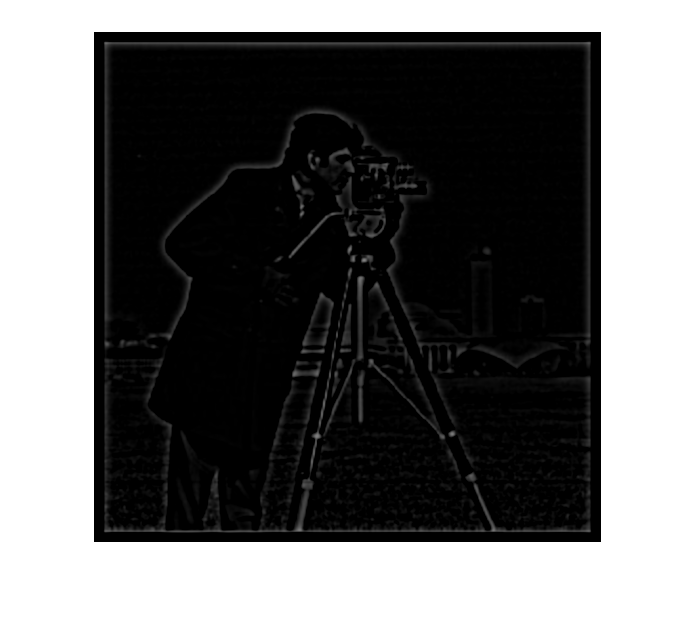

gaussian_img = dogFilter(5,1,double(img2));
imshow(uint8(gaussian_img))

function [filtered_img] = convImg(img,mask)
    n = size(img);
    [k,~] = size(mask);
    kh = floor(k/2);
    
    % Adding padding
    pad_img = zeros(n(1)+2*kh,n(2)+2*kh);
    pad_img((kh+1):(n(1)+kh),(kh+1):(n(2)+kh)) = img;
    filtered_img = zeros(n(1),n(2));
    
    for i=1:(n(1)-k+1)
        for j=1:(n(2)-k+1)
            a = pad_img(i:i+k-1,j:j+k-1);
            value = sum(a.*mask,'all');
            filtered_img(i,j) = value;
        end
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [smooth_image] = gaussianFilter(sig,img)
    % kernel_size = 2*(ceil(3*sig)) + 1;
    kh = ceil(3*sig);
    % Gaussian mask
    [x,y] = meshgrid(-kh:kh, -kh:kh);
    gmask = exp((-1*(x.^2 + y.^2)/(2*sig^2)));
    gmask = gmask./sum(gmask,'all');
    
    % Applying convolution
    smooth_image = conv2(img,gmask,'same');
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [smooth_image] = dogFilter(sig1, sig2, img)
    
    kh = 10;
    % Computing Gaussian mask 1
    sig = sig1;
    [x,y] = meshgrid(-kh:kh, -kh:kh);
    gmask = exp((-1*(x.^2 + y.^2)/(2*sig^2)));
    gmask1 = gmask./sum(gmask,'all');
    
    % Gaussian mask 2
    sig = sig2;
    [x,y] = meshgrid(-kh:kh, -kh:kh);
    gmask = exp((-1*(x.^2 + y.^2)/(2*sig^2)));
    gmask2 = gmask./sum(gmask,'all');
    
    smooth_image = conv2(img,gmask2-gmask1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [smooth_image] = logFilter(sig, img)
    kh = ceil(3*sig);
    % Gaussian mask
    [x,y] = meshgrid(-kh:kh, -kh:kh);
    gmask = (((x.^2 + y.^2)./sig^4) - 1/sig^2).*exp((-1*(x.^2 + y.^2)/(2*sig^2)));
    gmask = gmask./sum(gmask,'all');
    
    % Applying convolution
    smooth_image = conv2(img,gmask,'same');
    
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%